# The monostatic way

rng('default');                                            % Set the random number generator for reproducibility
carrierFrequency = 30e9;                                   % Carrier frequency (Hz)
wavelength = freq2wavelen(carrierFrequency);

Transmitter location.

txPosition = [0; 0; 0];                                    % Base station location

Create a transmitter object and set the transmit power to 46 dBm.

txPower = 46;                                             % dBm
transmitter = phased.Transmitter('PeakPower', db2pow(txPower-30), 'Gain', 0);

A ULA with multiple antennas is used instead of a single isotropic antenna to enable beamforming and angle-of-arrival estimation, which are essential for realistic 5G ISAC sensing.

numTxAntennas = 8;                                         % Number of antenna elements at the Tx array 
element = phased.IsotropicAntennaElement('BackBaffled', true);
txArray = phased.ULA(numTxAntennas, wavelength/2, 'Element', element);

Define the transmitter array orientation with no rotation, so its boresight points along the x-axis.

Use this line to change the orientation

txOrientationAxes = eye(3);                                % Tx array orientation

**Change**

**In monostatic** **sensing, the transmitter (Tx) and receiver (Rx) are co-located in the same BS and share the same antenna for transmission and reception**

rxPosition = txPosition ;                                  % User equipment location

Create a realistic receiver model with thermal noise, using a 5 dB noise figure and standard reference temperature.

receiver = phased.Receiver('AddInputNoise', true, 'Gain', 0, 'NoiseMethod', 'Noise figure',...
    'NoiseFigure', 5, 'ReferenceTemperature', 290);

 Define the receiver antenna array; the number of elements affects array gain and angular resolution, impacting sensing performance.

numRxAntennas = numTxAntennas;                                         % Number of antenna elements at the Rx array
rxArray = txArray;

The receive array is oriented  aligned with the Tx- direction because both are the same system.

**change**

rxOrientationAxes = txOrientationAxes %rotz(-90);                            % Rx array orientation

rxOrientationAxes =      1     0     0
     0     1     0
     0     0     1


Scatterers are simplified point reflectors representing objects in the environment; they are used to model signal reflections and multipath in a simple and computationally efficient way.

regionOfInterest = [0 120; -80 80];% Region of interest % Define the region where scatterers are placed: x ranges from 0 to 120 and y from -80 to 80.                      % Region of interest
numScatterers = 40;                % Number of scatterers distributed with the region of interest

% Randomly distributed scatterers
[scatterers.Positions, scatterers.ReflectionCoefficients] = ...
    helperGenerateStaticScatterers(numScatterers, regionOfInterest);

Scatterer motion affects Doppler and system performance; here they are set as static to model the environment, while moving targets are handled separately.different topologies may perform differently in dynamic scenarios.

scatterers.Velocities = zeros(size(scatterers.Positions));

In the supporting functions, two predefined moving targets are explicitly defined with fixed trajectories and constant velocities for the sensing scenario. 

targets.Trajectories = helperGetTargetTrajectories();

ans = 2×5 table
    Trajectory    Start Position [x, y]    End Position [x, y]    Length (m)    Speed (m/s)
    __________    _____________________    ___________________    __________    ___________

       "1"              {[25 -5]}               {[40 30]}           38.079        9.5197   
       "2"              {[70 30]}               {[80 10]}           22.361        5.5902   



% Target reflection coefficients
numTargets = numel(targets.Trajectories);
targets.ReflectionCoefficients = exp(1i*(2*pi*rand(1, numTargets)));

Enable direct path (LoS) propagation between Tx and Rx; in addition to reflected paths, the signal also includes a direct line-of-sight component. If set to false, only reflected paths are considered. Ignore polarization effects, treating the signal without distinguishing between horizontal and vertical components for simplicity.

**change**

**The simulationPath changes to false**

channel = phased.ScatteringMIMOChannel('CarrierFrequency', carrierFrequency, 'TransmitArray', txArray,...
    'TransmitArrayPosition', txPosition, 'ReceiveArray', rxArray, 'ReceiveArrayPosition', rxPosition,...
    "TransmitArrayOrientationAxes", txOrientationAxes, "ReceiveArrayOrientationAxes", rxOrientationAxes,... , 
    'SimulateDirectPath', false, 'ScattererSpecificationSource', 'Input Port', ...
    'ChannelResponseOutputPort',true,'Polarization','None');

Visualize the scenario using the `helperVisualizeScatteringMIMOChannel` helper function.

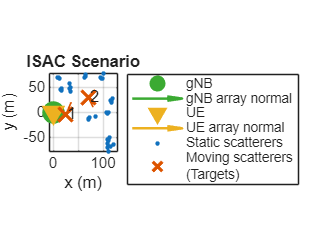

helperVisualizeScatteringMIMOChannel(channel, scatterers.Positions, targets.Trajectories);
title('ISAC Scenario');

# **5G Waveform Configuration**

Set system parameters for 5G NR. Let the channel bandwidth be 50 MHz.

channelBandwidth = 50;                                     % MHz - transmission bandwidth and guardbands

Set the bandwidth occupancy. This is the ratio between the transmission bandwidth and channel bandwidth. A lower bandwidth occupancy increases the size of guardbands, reducing spectral emissions at the cost of reduced spectral efficiency.

bandwidthOccupancy = 0.9;                                  % Ratio of transmission bandwidth to channel bandwidth

 Let the subcarrier spacing be 60 kHz.

subcarrierSpacing = 60;                                    % Subcarrier spacing (kHz)

Use the `helperGet5GWaveformConfiguration` to create a 5G waveform configuration.

Step 1:Create the 5G signal configuration

Step 2:MATLAB calculates all derived OFDM parameters

waveformConfig = helperGet5GWaveformConfiguration(channelBandwidth, bandwidthOccupancy, subcarrierSpacing);
waveformInfo = nrOFDMInfo(waveformConfig.Carrier)

waveformInfo = struct with fields:
                   Nfft: 1024
             SampleRate: 61440000
    CyclicPrefixLengths: [104 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 104 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72 72]
          SymbolLengths: [1128 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1128 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 … ] (1×56 double)
              Windowing: 36
           SymbolPhases: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
         SymbolsPerSlot: 14
       SlotsPerSubframe: 4
          SlotsPerFrame: 40


Compute the actual occupied transmission bandwidth from the subcarrier spacing and the number of resource blocks (12 subcarriers per RB).

transmissionBandwidth = subcarrierSpacing*1e3*waveformConfig.Carrier.NSizeGrid*12; % Bandwidth of resource blocks in Hz
fprintf("Transmission bandwidth: %.2f MHz\n",transmissionBandwidth*1e-6);

Transmission bandwidth: 44.64 MHz


Match the channel sample rate with the waveform to ensure consistent time-domain signal processing.

channel.SampleRate = waveformInfo.SampleRate;

**DM-RS parameters.Explained in NR PDSCH**

waveformConfig.PDSCH.DMRS.DMRSTypeAPosition = 2;           % Mapping type A only. First DM-RS symbol position is 2
waveformConfig.PDSCH.DMRS.DMRSLength = 1;                  % Single-symbol DM-RS
waveformConfig.PDSCH.DMRS.DMRSAdditionalPosition = 2;      % Additional DM-RS symbol positions (max range 0...3)
waveformConfig.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;     % Number of CDM groups without data
waveformConfig.PDSCH.DMRS.DMRSConfigurationType = 1;       % DM-RS configuration type (1,2)

Visualize one resource block of the configured resource grid.

# Monostatic case

**Note: you do NOT have to change that part of the code.**

**That calculation:**

**maxDoppler = 1/(2*Mt*ofdmSymbolDuration);**

**does not calculate the real Doppler of the target. It calculates the maximum unambiguous Doppler that can be estimated with the time separation between DM-RS. That depends on the waveform, not on whether the geometry is monostatic or bistatic.**

**What does change between bistatic and monostatic is the physical Doppler of the target.**

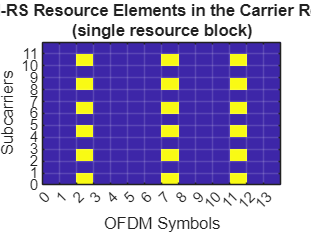

resourceGrid = nrResourceGrid(waveformConfig.Carrier, waveformConfig.PDSCH.NumLayers);
ind = nrPDSCHDMRSIndices(waveformConfig.Carrier, waveformConfig.PDSCH);
resourceGrid(ind) = nrPDSCHDMRS(waveformConfig.Carrier, waveformConfig.PDSCH);

helperVisualizeResourceGrid(abs(resourceGrid(1:12,1:14,1)));
title({'PDSCH DM-RS Resource Elements in the Carrier Resource Grid', '(single resource block)'});

The Doppler frequency represents how fast the channel varies over time due to the relative motion of scatterers or targets. Its value depends on the radial velocity of the object and the carrier frequency. The temporal spacing between DM-RS symbols does not set the Doppler itself, but it determines how often the channel is sampled and therefore the maximum Doppler that can be estimated unambiguously without aliasing.

% Compute maximum pilot signal separation in time
[~,pdschInfo] = nrPDSCHIndices(waveformConfig.Carrier,waveformConfig.PDSCH);
Mt = max(diff(pdschInfo.DMRSSymbolSet));

% Duration of an OFDM symbol in seconds
ofdmSymbolDuration = max(waveformInfo.SymbolLengths)/waveformInfo.SampleRate;

maxDoppler = 1/(2*Mt*ofdmSymbolDuration);
fprintf('Maximum unambiguous Doppler shift: %.2f kHz\n', maxDoppler*1e-3);

Maximum unambiguous Doppler shift: 5.45 kHz


**Once the maximum unambiguous Doppler shift is obtained, it is converted into the maximum target radial velocity that can be estimated without ambiguity for the current waveform configuration. MAXIMA VELOCIDAD**

maxVelocity = dop2speed(maxDoppler, wavelength)/2;
fprintf('Maximum unambiguous velocity: %.2f m/s\n', maxVelocity);

Maximum unambiguous velocity: 27.22 m/s


**The maximum unambiguous time delay is determined by the frequency-domain spacing of the DM-RS pilots. This depends only on the waveform configuration (subcarrier spacing and pilot distribution) and is independent of the sensing topology. Therefore, this expression remains the same for both monostatic and bistatic configurations.**

**The density of pilot signals in the frequency domain determines the maximum time delay that can be measured without causing aliasing**

% Compute pilot signal separation in frequency
Mf = min(diff(waveformConfig.PDSCH.DMRS.DMRSSubcarrierLocations));
maxDelay = 1/(2*Mf*subcarrierSpacing*1e3);
fprintf('Maximum time delay: %.2fe-6 s\n', maxDelay*1e6);

Maximum time delay: 4.17e-6 s


//EXPLICAR LINEAS DE ABAJO

channel.MaximumDelaySource = 'Property';
channel.MaximumDelay = maxDelay;

The frequency-domain spacing of DM-RS pilots determines the maximum unambiguous time delay that can be estimated, which directly sets the maximum observable target range.

**Change**

% Propagation speed
propagationSpeed = physconst("LightSpeed");

% Bistatic maximum range
maxRange = maxDelay*propagationSpeed/2;
fprintf('Maximum unambiguous bistatic range: %.2f m\n', maxRange);

Maximum unambiguous bistatic range: 624.57 m


CONCLUSION The DM-RS pilot pattern defines the sensing limits of the system: temporal pilot spacing determines the maximum unambiguous Doppler and observable target velocity, while frequency-domain pilot spacing determines the maximum unambiguous delay and observable target range.

Range resolution defines the minimum distance between two targets that can be distinguished; a larger transmission bandwidth reduces this value and improves range discrimination

% Range resolution
rangeResolution = propagationSpeed/transmissionBandwidth;
fprintf('Range resolution: %.2f m\n', rangeResolution);

Range resolution: 6.72 m


%Range resolution: 6.72 m
%Targets that are separated in range by less than the system'

This resolution is sufficient for resolving the targets in the scenario.

# **Channel Simulation and Sensing Data Processing**

Simulate a limited set of sensing frames at discrete time instants to capture target motion while keeping the computational cost manageable

% Number of PDSCH frames to simulate
numSensingFrames = 10;

% Time step between simulated PDSCH frames (s)
dt = 0.4;

% Simulation times
%changes
t = (0:numSensingFrames-1)*dt;


The estimated channel matrix is treated as a radar data cube: subcarriers map to range, OFDM symbols to slow-time, receive antennas to AoA, and reference signal ports to AoD

numAoA defines the number of candidate AoA values tested by the algorithm; these are search angles,not actual echoes, and for a ULA they are scanned over the visible angular range from -90 to 90 degrees

Compute the theoretical spatial response of the receive array for all candidate AoA values, so the measured signal can later be matched against them to estimate the arrival direction

numAoA = ceil(2*pi*numRxAntennas);                         % AoA grid size
aoaGrid = linspace(-90, 90, numAoA);                       % AoA grid

% Receive array steering vectors
rxSteeringVector = phased.SteeringVector(SensorArray=channel.ReceiveArray);
rxsv = rxSteeringVector(carrierFrequency, aoaGrid);

**Change in this part changes could be done but with this its okay **

**the changes would be **numAoD = numAoA;aodGrid = aoaGrid

The same with the TX

numAoD = ceil(2*pi*numTxAntennas);                         % AoD grid size
aodGrid = linspace(-90, 90, numAoD);                       % AoD grid

% Transmit array steering vectors
txSteeringVector = phased.SteeringVector(SensorArray=channel.TransmitArray);
txsv = txSteeringVector(carrierFrequency, aodGrid);

A dictionary of frequency-domain phase signatures associated with different candidate distance ranges. Define the monostatic range search grid from 0  m to 100 m; In monostatic : BS → target → BS The range is: R≥0 There is no such thing as:negative distance to the target, the upper limit keeps the map and processing manageable, and the grid is sampled at one quarter of the nominal range resolution to obtain a smoother range map without improving the true physical resolution. A grid is the set of candidate physical values to be tested, while a bin is a discrete position in the processed range axis; this line converts the bistatic range grid from meters into equivalent fast-time bins, adding the baseline because the delay depends on the total Tx-target-Rx path. These lines complete the range-axis setup: numSubcarriers gives the total number of occupied NR subcarriers (12 per resource block), k defines the subcarrier index vector, and rngsv builds the fast-time steering vectors, i.e., the theoretical phase response across subcarriers for each candidate range, following the DFT-like form exp(j*2*pi*k*n/N). numSubcarriers is divided twice for normalization

**Change**

% Limit the maximum monostatic range of interest to 100 meters
rangeGrid = 0:rangeResolution/4:100;                     % monostatic range grid
numRange = numel(rangeGrid);                               % monostatic range grid size

% Fast-time steering vectors 
rangeFFTBins = (2*rangeGrid)/rangeResolution;
numSubcarriers = waveformConfig.Carrier.NSizeGrid*12;
k = (0:numSubcarriers-1).';
rngsv = (exp(2*pi*1i*k*rangeFFTBins/numSubcarriers)/numSubcarriers);

**Set up a 2-D CFAR detector to find target candidates in the monostatic range-AoA map by comparing each cell against an adaptive local threshold estimated from neighboring training cells, while guard cells prevent target energy from biasing the background estimate**

- `numGuardCellsRange = ceil(rangeResolution/(rangeGrid(2)-rangeGrid(1))) + 1; `

- `numGuardCellsAoA = ceil(aoaResolution/(aodGrid(2)-aodGrid(1))) + 1;`

Guard cells are the cells around the cell under test (CUT) that are excluded from the CFAR background estimate because they may contain energy from the same target and bias the threshold; this line computes how many guard cells are needed in range by comparing the physical range resolution with the spacing between consecutive points of the range grid, i.e., how many map cells correspond approximately to one range-resolution width

- `aoaResolution = ap2beamwidth((numRxAntennas-1)*channel.SRX.ReceiveAntennaArray.ElementSpacing, wavelength);`

The angular resolution is approximated using the array beamwidth, i.e., the angular width of the main lobe; this beamwidth is estimated from the array aperture, where for a ULA the aperture is approximately (M-1)*d, with M the number of antennas and d the element spacing, so a larger aperture gives a narrower beamwidth and a better angular resolution

- `cfar2D = phased.CFARDetector2D('GuardBandSize'``,[numGuardCellsRange numGuardCellsAoA], ``'TrainingBandSize'``, [4 6],``...  ``'ProbabilityFalseAlarm'``, 1e-35, ``'OutputFormat'``, ``'CUT result'``, ``'ThresholdOutputPort'``, false);`

Create and configure the 2-D CFAR detector, which defines the detection criterion over the monostatic range-AoA map. GuardBandSize sets the guard region around each CUT in the range and angular axes so target energy does not bias the background estimate. TrainingBandSize defines how many cells beyond the guard band are used to estimate the local background; [4 6] is a practical design choice for this example, since too few training cells make the threshold unstable, while too many make the estimate less local, increase computational cost, and reduce useful cells near the map edges. ProbabilityFalseAlarm sets the target false-alarm probability to 1e-4, which is chosen by the detector designer rather than derived directly from the channel physics. OutputFormat set to 'CUT result' means the detector returns, for each tested CUT, whether it exceeds the adaptive threshold or not. ThresholdOutputPort set to false means the detector does compute an adaptive threshold internally, but it does not return that threshold explicitly, since this example is focused on detections for clustering and tracking rather than threshold analysis

`% Compute indices of the cells under test`

`offsetIdxs = cfar2D.TrainingBandSize + cfar2D.GuardBandSize;`

`rangeIdxs = offsetIdxs(1)+1:numel(rangeGrid)-offsetIdxs(1);    `

`angleIdxs = offsetIdxs(2)+1:numel(aoaGrid)-offsetIdxs(2);`

`[sumRangeIdxs, aoaIdxs] = meshgrid(rangeIdxs, angleIdxs);`

`cutidx = [sumRangeIdxs(:).'; aoaIdxs(:).'];`

 These lines do not perform detection yet; instead, they prepare which map cells can be evaluated as CUTs by the CFAR detector. offsetIdxs computes the total margin that must be left around each CUT in each axis so that both the guard cells and the training cells fit, where offsetIdxs(1) is the required margin in range and offsetIdxs(2) is the required margin in angle. For this reason, rangeIdxs and angleIdxs exclude the map borders, since a CUT too close to an edge would not have enough surrounding cells to build the full CFAR window. Then, meshgrid generates all possible combinations of valid range and angle indices, and finally cutidx formats them as required by the detector: one row with the range indices and one row with the angular indices of all valid CUTs

% Number of guard cells in range
numGuardCellsRange = ceil(rangeResolution/(rangeGrid(2)-rangeGrid(1))) + 1;

% Resolution in AoA domain
aoaResolution = ap2beamwidth((numRxAntennas-1)*channel.ReceiveArray.ElementSpacing, wavelength);

% Number of guard cells in AoA
numGuardCellsAoA = ceil(aoaResolution/(aodGrid(2)-aodGrid(1))) + 1;

% Create a 2-D CFAR detector
cfar2D = phased.CFARDetector2D('GuardBandSize',[numGuardCellsRange numGuardCellsAoA], 'TrainingBandSize', [4 6],...
    'ProbabilityFalseAlarm', 1e-5, 'OutputFormat', 'CUT result', 'ThresholdOutputPort', false);

% Compute indices of the cells under test
offsetIdxs = cfar2D.TrainingBandSize + cfar2D.GuardBandSize;

rangeIdxs = offsetIdxs(1)+1:numel(rangeGrid)-offsetIdxs(1);    
angleIdxs = offsetIdxs(2)+1:numel(aoaGrid)-offsetIdxs(2);

[sumRangeIdxs, aoaIdxs] = meshgrid(rangeIdxs, angleIdxs);
cutidx = [sumRangeIdxs(:).'; aoaIdxs(:).'];

The CFAR algorithm can produce multiple detections around the true target positions. These detections are typically clustered together to obtain a single detection. Create a DBSCAN clusterer object.

clusterer = clusterDBSCAN();

Tracking estimates not only where a target is at each instant, but also its velocity, trajectory, and temporal identity across frames. The tracker receives noisy monostatic range and AoA measurements and uses them to estimate a Cartesian state vector [x; vx; y; vy]. For this, it uses the Tx and Rx orientations reformatted as rotation matrices so that the angular geometry is correctly referred to the global reference frame. The helperConfigureTracker function creates the tracker already adapted to this specific problem. In addition, targetStateEstimates preallocates memory to store the estimated states of up to 10 tracks across all frames, and trackIDs initializes the list of track identifiers that will be assigned as the tracker creates and updates trajectories

tracker = helperConfigureTracker(txPosition, rxPosition, txOrientationAxes, rxOrientationAxes, rangeResolution, aoaResolution);

% Preallocate space to store estimated target state vectors [x; vx; y; vy]
% Preallocate space for 10 tracks
targetStateEstimates = zeros(4, numSensingFrames, 10);
trackIDs = [];

To generate visualizations showing the ISAC scenario together, the true target positions, target detections, and tracks, set `generateVisualizations` to true.

% Produce visualizations
generateVisualizations = true;

if generateVisualizations
    scenarioCFARResultsFigure = figure;
    tl = tiledlayout(scenarioCFARResultsFigure, 1, 2, 'Padding', 'tight', 'TileSpacing', 'tight');


Use the `helperTheaterPlotter` to visualize the scenario, target trajectories, detections, and tracks. 

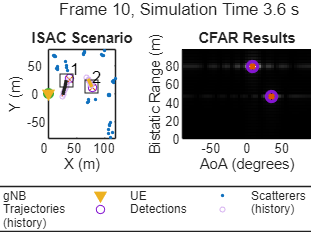


Simulating frame at time 0 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 0.4 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 0.8 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 1.2 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 1.6 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 2 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 2.4 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 2.8 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 3.2 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000



Simulating frame at time 3.6 s



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


    scenarioPlotter = helperTheaterPlotter(tl);
    scenarioPlotter.plotTxAndRx(txPosition, rxPosition);
    scenarioPlotter.plotTrajectories(targets.Trajectories, t);
    scenarioPlotter.plotScatterers(scatterers.Positions);
    title(scenarioPlotter, 'ISAC Scenario');

Use `helperCFARResultsVisualizer` to visualize CFAR results.

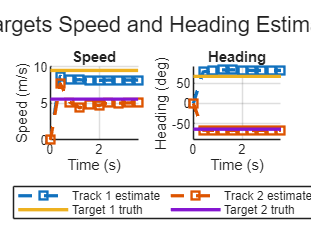

    cfarResultsVisualizer = helperCFARResultsVisualizer(tl);

    xlabel(cfarResultsVisualizer, 'AoA (degrees)');
    ylabel(cfarResultsVisualizer, 'Bistatic Range (m)');
    title(cfarResultsVisualizer, 'CFAR Results');
end

Run the simulation transmitting and processing one PDSCH frame at a time.

 ESTO ES PARA EL CASO BIESTATICO PARA EL CASO MONOESTATICO CAMBIA SEGURO

% Number of symbols per frame
numSymbolsPerFrame = waveformInfo.SlotsPerFrame*waveformInfo.SymbolsPerSlot;

% Transmit and process one PDSCH frame at a time
for i = 1:numSensingFrames
    fprintf('\nSimulating frame at time %g s\n', t(i));
    
    % helperSimulateLinkSingleFrame returns a 4-D matrix 
    % numSubcarriers x numSymbolsPerFrame x numRxAntennas x numTxAntennas
    sensingCSI = helperSimulateLinkSingleFrame(transmitter, receiver, channel, waveformConfig, scatterers, targets, t(i));

    % Reset the channel between PDSCH frame transmissions
    reset(channel);

    % To filter the static scatterers out, put a zero in the first Doppler
    % bin
    X = fft(sensingCSI, [], 2);
    X(:, 1, :, :) = 0;
    x = ifft(X, [], 2);

    % Process data cube along the AoD dimension
    x = permute(x, [4 1 3 2]);
    x = txsv'*reshape(x, numTxAntennas, []);

    % Process data cube along the range dimension
    x = permute(reshape(x, numAoA, numSubcarriers, numRxAntennas, numSymbolsPerFrame), [2 3 1 4]);
    x = rngsv.'*reshape(x, numSubcarriers, []);

    % Process data cube along the AoA dimension
    x = permute(reshape(x, numRange, numRxAntennas, numAoD, numSymbolsPerFrame), [2 1 3 4]);
    x = rxsv'*reshape(x, numRxAntennas, []);

    % Average over AoDs and symbols
    x = reshape(x, numAoA, numRange, []);
    sumRangeAoAMap = sqrt(sum(abs(x).^2, 3)).';

    % Perform 2-D CFAR detection over range-AoA map
    cutResult = cfar2D(sumRangeAoAMap, cutidx);
    detectionIdxs = cutidx(:, cutResult);
    detectionValues = [rangeGrid(detectionIdxs(1,:)); aoaGrid(detectionIdxs(2,:))];    

    % Cluster CFAR detections
    [~, clusterids] = clusterer(detectionValues.');
    uniqClusterIds = unique(clusterids);

    % Loop over detection clusters, and for each cluster find a
    % center
    m = numel(uniqClusterIds);
    clusteredDetections = zeros(2, m);

    for j = 1:m
        idxs = clusterids == uniqClusterIds(j);
        d = detectionValues(:, idxs);

        % Represent a cluster of detections with its center 
        clusteredDetections(:, j) = mean(d, 2);
    end

    % Format detections so that they can be processed by the tracker
    %si quitas el ; se pone mas informacion al runear
detections = helperFormatDetectionsForTracker(clusteredDetections, t(i), rangeResolution, aoaResolution);
    %changes
   
    % Pass detections to the tracker
    tracks = tracker(detections);

    % Store target state estimates
    for it = 1:numel(tracks)
        id = tracks(it).TrackID;
        trackIDs = union(trackIDs, id);        
        targetStateEstimates(:, i, id) = tracks(it).State;
    end    
    
    % Visualization
    if generateVisualizations
        % Plot true target positions
        targetPositions = zeros(numTargets, 3);
        for it = 1:numTargets
            targetPositions(it, :) = lookupPose(targets.Trajectories{it}, t(i));
        end
        scenarioPlotter.plotTargetPositions(targetPositions);
       
        % Plot target positions estimated from the detections
        measuredPositions = helperGetMonostaticCartesianMeasurement(clusteredDetections, rxPosition, rxOrientationAxes);
        scenarioPlotter.plotDetections(measuredPositions);
        scenarioPlotter.plotTracks(tracks);
    
        % Visualize CFAR results 
        %change
        [trueRrx, trueAoA] = rangeangle(targetPositions.', rxPosition, rxOrientationAxes);
        [trueRtx, trueAoD] = rangeangle(targetPositions.', txPosition, txOrientationAxes);
        trueMonostaticRange = trueRrx ;
    
        cfarResultsVisualizer.plotCFARImage(aoaGrid, rangeGrid, sumRangeAoAMap);
       
         cfarResultsVisualizer.plotTruth([trueMonostaticRange; trueAoA(1, :)]);
        cfarResultsVisualizer.plotClusteredDetections(clusteredDetections);

        sgtitle(scenarioCFARResultsFigure, sprintf('Frame %d, Simulation Time %.1f s', i, t(i)), 'FontSize' ,10);
          drawnow;
    end
end

The simulation results show that radar detections in bistatic range-AoA space can be successfully formed by processing the channel matrix estimates. These detections are close to the true target positions. Subsequently, the tracker utilizes these detections to estimate targets' states, which consist of positions and velocities in Cartesian coordinates.

Use `helperPlotSpeedEstimationResults` helper function to compare target speed and heading estimates based on the tracker outputs with the true values.

helperPlotSpeedEstimationResults(t, targets.Trajectories, targetStateEstimates, trackIDs)

Notice that the tracker requires at least two initial detections to initiate a track and start computing velocities. This is why it can take several track updates before the speed and the heading estimates converge to the true values.

# Supporting Functions

function tracker = helperConfigureTracker(txPosition, rxPosition, txOrientation, rxOrientation, rangeResolution, aoaResolution)
%changes
   % Cambiar a configuración monostática
    sensorSpec = trackerSensorSpec("aerospace", "radar", "monostatic");

    % Asignamos la misma posición y orientación para emisor y receptor
    sensorSpec.PlatformPosition = rxPosition;  % O txPosition, because they are the same
    sensorSpec.PlatformOrientation = rxOrientation.';  % O txOrientation

    % Eliminar propiedades no soportadas en monostático
    % Ya no necesitas 'ReceiverFieldOfView' ni otras propiedades de orientación específicas

    % Configuración de resolución y límites
    sensorSpec.RangeResolution = rangeResolution;
    sensorSpec.AzimuthResolution = aoaResolution;
    sensorSpec.DetectionProbability = 0.9;

    % Configuración de objetivos (targets)
    targetSpec = trackerTargetSpec('custom');
    targetSpec.StateTransitionModel = targetStateTransitionModel('constant-velocity');
    targetSpec.StateTransitionModel.NumMotionDimensions = 2;
    targetSpec.StateTransitionModel.VelocityVariance = 15^2/3*eye(2);
    targetSpec.StateTransitionModel.AccelerationVariance = 0.01^2/3*eye(2);    

    % Crear el tracker
    tracker = multiSensorTargetTracker(targetSpec, sensorSpec, "jipda"); 
    tracker.ConfirmationExistenceProbability = 0.98; 
    tracker.MaxMahalanobisDistance = 10;
end

function detections = helperFormatDetectionsForTracker(clusteredDetections, currentTime, rangeResolution, aoaResolution)
%changes
   % clusteredDetections is a 2 x M matrix:
    % row 1 -> monostatic range
    % row 2 -> AoA azimuth angle

    numDetections = size(clusteredDetections, 2);

    detections = struct;

    % Look fields: describe where/when the monostatic sensor is looking
    detections.LookTime = currentTime;
    detections.LookAzimuth = 0;
    detections.LookElevation = 0;

    % Per-detection fields
    detections.DetectionTime = ones(1, numDetections) * currentTime;
    detections.SensorIndex = ones(1, numDetections);

    % Main measurements expected by AerospaceMonostaticRadar
    detections.Range = clusteredDetections(1, :);
    detections.Azimuth = clusteredDetections(2, :);
    detections.Elevation = zeros(1, numDetections);

    % Add range-rate fields in case this MATLAB release expects them
    detections.RangeRate = zeros(1, numDetections);

    % Accuracy fields
    detections.RangeAccuracy = ones(1, numDetections) * rangeResolution/8;
    detections.AzimuthAccuracy = ones(1, numDetections) * aoaResolution/12;
    detections.ElevationAccuracy = ones(1, numDetections) * aoaResolution/12;
    detections.RangeRateAccuracy = ones(1, numDetections) * 1;

    % Optional measurement matrix
    detections.Measurements = [detections.Range; detections.Azimuth; detections.Elevation];

    % Empty measurement parameters, one per detection
    detections.MeasurementParameters = repmat(struct(), 1, numDetections);
end

TConvert monostatic range-AoA detections into Cartesian coordinates. In the monostatic configuration, Tx and Rx are co-located at the same base station, so each detection can be interpreted directly as a polar measurement with respect to the receiver: range = BS-target distance and AoA = arrival direction. The function first converts these local polar measurements into local Cartesian coordinates, then rotates them according to the receiver array orientation and translates them to the global scenario reference frame

function meascart = helperGetMonostaticCartesianMeasurement(dets, rxPosition, rxOrientationAxes)
    if ~isempty(dets)
        % dets(1,:) = monostatic range
        % dets(2,:) = AoA in degrees

        r = dets(1, :);
        az = dets(2, :);

        % Convert local polar measurements [range, AoA] to local Cartesian coordinates
        xLocal = r .* cosd(az);
        yLocal = r .* sind(az);
        zLocal = zeros(size(r));

        meascartLocal = [xLocal; yLocal; zLocal];

        % Rotate from local Rx coordinates to global coordinates and translate to Rx position
        meascart = rxPosition + rxOrientationAxes * meascartLocal;
    else
        meascart = [];
    end
end

function trajectories = helperGetTargetTrajectories()
    % Target #1
    waypoints = [25 -5 0;
                 40 30 0];
    timeOfArrival = [0 4];
    traj1 = waypointTrajectory(waypoints,timeOfArrival);

    % Target #2
    waypoints = [70 30 0;
                 80 10 0];

    timeOfArrival = [0 4];
    traj2 = waypointTrajectory(waypoints,timeOfArrival);
    
    trajectories = {traj1, traj2};

    Trajectory = strings(numel(trajectories), 1);
    Speed = zeros(numel(trajectories), 1);
    Length = zeros(numel(trajectories), 1);
    Start = cell(numel(trajectories), 1);
    Stop = cell(numel(trajectories), 1);

    for i = 1:numel(trajectories)
        Trajectory(i) = i;
        Start{i} = trajectories{i}.Waypoints(1, 1:2);
        Stop{i} = trajectories{i}.Waypoints(end, 1:2);
        Length(i) = vecnorm(trajectories{i}.Waypoints(1, :) - trajectories{i}.Waypoints(end, :));
        Speed(i) = max(trajectories{i}.GroundSpeed);
    end

    table(Trajectory, Start, Stop, Length, Speed, 'VariableNames',...
        {'Trajectory', 'Start Position [x, y]', 'End Position [x, y]', 'Length (m)', 'Speed (m/s)'})
end

function helperPlotSpeedEstimationResults(t, trajectories, targetStateEstimates, trackIDs)
    fig = figure;
    tl = tiledlayout(fig, 1, 2);
    speedAxes = nexttile(tl);
    hold(speedAxes, 'on');
    
    xlabel(speedAxes, 'Time (s)');
    ylabel(speedAxes, 'Speed (m/s)');
    grid(speedAxes, 'on');
    title(speedAxes, 'Speed');
    xlim(speedAxes, [t(1) t(end)]);
    lgd = legend(speedAxes, 'Location', 'southeast', 'Orientation', 'horizontal', 'NumColumns', 2);
    lgd.Layout.Tile = 'south';
    
    headingAxes = nexttile(tl);
    hold(headingAxes, 'on');
    xlabel(headingAxes, 'Time (s)');
    ylabel(headingAxes, 'Heading (deg)');
    grid(headingAxes, 'on');
    title(headingAxes, 'Heading');
    ylim(headingAxes, [-90 90]);    
    xlim(headingAxes, [t(1) t(end)]);

    sgtitle(fig, 'Targets Speed and Heading Estimates')
    
    for it = 1:numel(trackIDs)
        id = trackIDs(it);
        vx = targetStateEstimates(2, :, id);
        vy = targetStateEstimates(4, :, id);
    
        speedEstimate = sqrt(vx.^2 + vy.^2);
        headingEstimate = atan2d(vy, vx);
        plot(speedAxes, t, speedEstimate, 's--', 'LineWidth', 2, 'DisplayName', sprintf('Track %d estimate', trackIDs(it)));
        plot(headingAxes, t, headingEstimate, 's--', 'LineWidth', 2);
    end
    
    for it = 1:numel(trajectories)
        [~, ~, velocity] = lookupPose(trajectories{it}, t);
        trueSpeed = sqrt(velocity(:, 1).^2 + velocity(:, 2).^2);
        trueHeading = atan2d(velocity(:, 2), velocity(:, 1));
        
        plot(speedAxes, t, trueSpeed, '-', 'LineWidth', 2, 'DisplayName', sprintf('Target %d truth', it));
        plot(headingAxes, t, trueHeading, '-', 'LineWidth', 2);
    end
end